### 由于这个作业跟homework4 用的是一个模型，所以就整在一起了

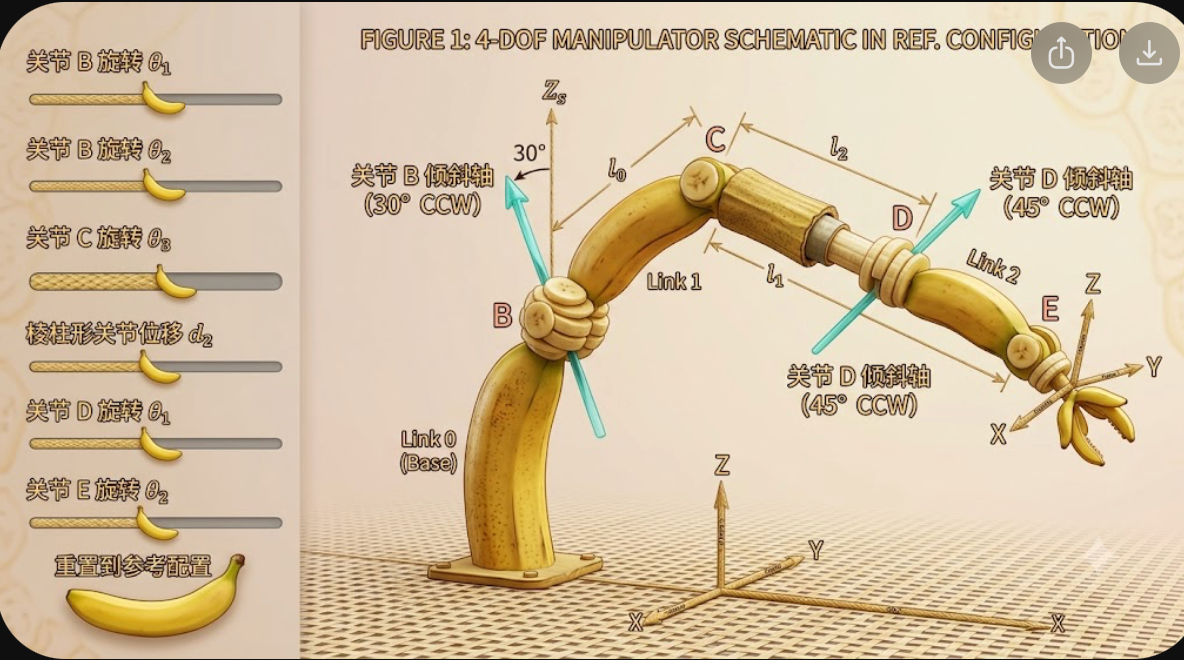

clc;clear
import robo.*

%initial Parameters setting
l0 = 0.6; l1 = 0.43; l2 = 0.21;

theta1 = 59;  theta3 = -107; theta4 = 45; %revolute joint 
theta1_R = deg2rad(theta1); theta3_R = deg2rad(theta3); theta4_R = deg2rad(theta4);
theta2 = 0.55; %位移 prismatic joint 

theta_dot = [0.4;-0.1;0.28;0.3]

theta_dot =     0.4000
   -0.1000
    0.2800
    0.3000



F = 100 * eye(6); %因为给的比较巧哈
F1 = F(:,1)

F1 =    100
     0
     0
     0
     0
     0


F2 = F(:,2);
F3 = F(:,3);
F4 = F(:,4);
F5 = F(:,5);
F6 = F(:,6);

q1 = [0;0;l0]; %joint B  in spatial frame
q3 = [0;l1;l0];%joint CD in spatial frame
q4 = [0;l1+l2;l0]; %joint of tool in spatial frame
d = q3; %这玩意是一个 prismatic joint 所以假设先这样吧
%================
%接下里来表示gst0，tool frame 在spatial frame里的坐标

gst0  =  gmat(eye(3),q4); %用来生成homo的方程（gmat）

omega1 = [0;-sin(pi/6);cos(pi/6)]; %题目里的初始条件关于 joint的旋转是与Z轴成30度角
v2 = [0; 0; 1];                    %题目里面说这个是prismatic joint aling y-z plane
omega3 = [0; -sin(pi/4);cos(pi/4)];%题目里面说这个关于 z轴成45度角逆时针
omega4 = [0; 0; 1];% 构建xi

xi1 = [-hatm(omega1)*q1;omega1];
xi2 = [v2              ;[0;0;0]];
xi3 = [-hatm(omega3)*q3;omega3];
xi4 = [-hatm(omega4)*q4;omega4];

G1 = gtwist(xi1,theta1_R); %注意这里是输入rad，别整错了
G2 = gtwist(xi2,theta2); %这里前面设置了是0.5
G3 = gtwist(xi3,theta3_R);
G4 = gtwist(xi4,theta4_R);

gst = G1 * G2 * G3 * G4 *gst0; %这里不是解IK，所以用gst来表示

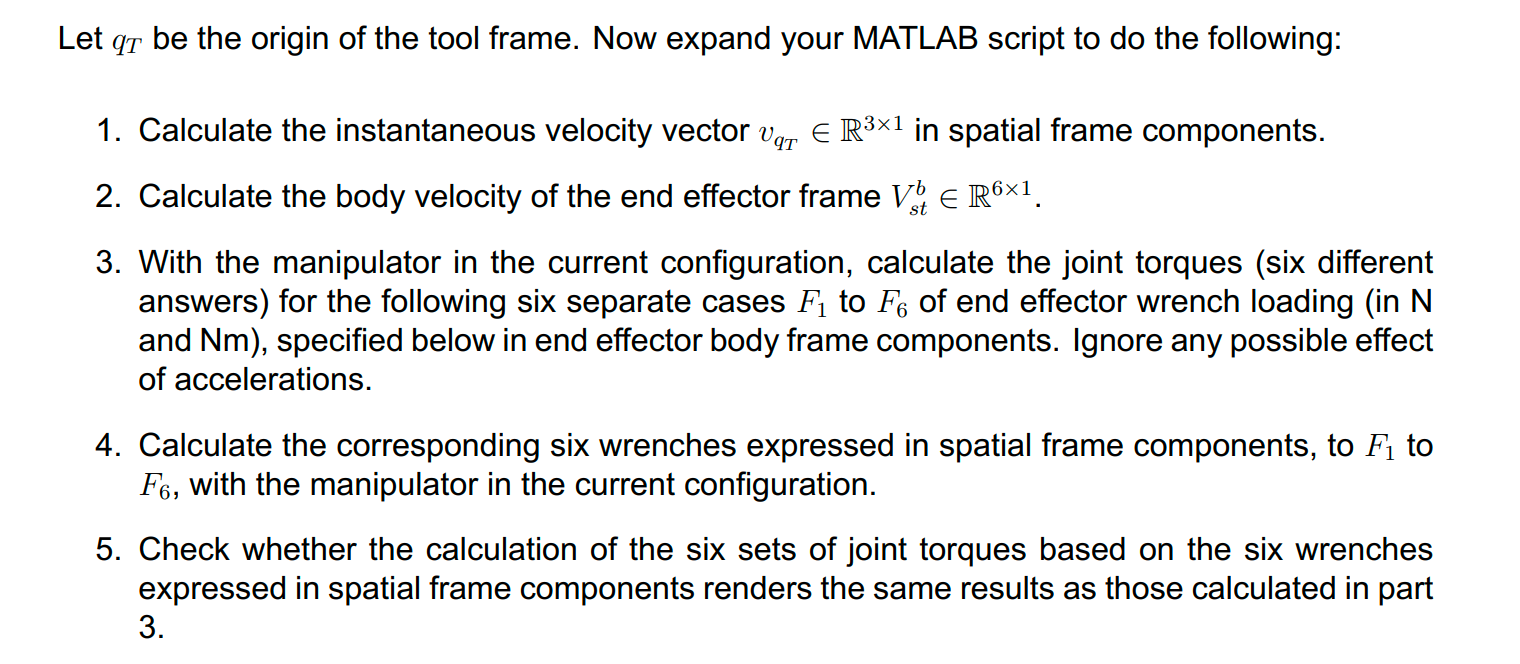

qT = [0;l1+l2;l0];
%==========
g_s_0 = eye(4);
g_s_1 = G1;
g_s_2 = G1 * G2; %这个鬼地方要注意矩阵乘法的顺序啊
g_s_3 = G1 * G2 * G3; %Jacobian是叠加，所以要有顺序的叠加

xi2_p = adjoint(g_s_1)* xi2;
xi3_p = adjoint(g_s_2)* xi3;
xi4_p = adjoint(g_s_3)* xi4;

J_s = [xi1 , xi2_p, xi3_p, xi4_p];

Vs = J_s * theta_dot

Vs =     0.4337
    0.4945
   -0.0759
    0.2650
   -0.3626
    0.7829


Vb = adjoint(inv(gst)) * Vs

Vb =    -0.0436
   -0.1127
   -0.2313
   -0.4183
   -0.2783
    0.7498


J_b = adjoint(inv(gst)) * J_s

J_b =    -0.2692   -0.9351   -0.1050    0.0000
   -0.3499    0.0212    0.1050    0.0000
   -0.4897    0.3538   -0.0000   -0.0000
   -0.6958         0   -0.5000    0.0000
   -0.3458         0   -0.5000    0.0000
    0.6295         0    0.7071    1.0000



tau = J_b' * F

tau =   -26.9188  -34.9915  -48.9749  -69.5815  -34.5783   62.9505
  -93.5075    2.1230   35.3814         0         0         0
  -10.5000   10.5000   -0.0000  -50.0000  -50.0000   70.7107
    0.0000    0.0000   -0.0000    0.0000    0.0000  100.0000



F_s = adjoint(inv(gst))' * F

F_s =    70.9774  -19.7019   67.6317         0         0         0
   25.2788   96.7381    1.6516         0         0         0
  -65.7510   15.9242   73.6426         0         0         0
  -45.5406  -83.5024   23.4682   70.9774  -19.7019   67.6317
   33.7500  -10.4825   97.4144   25.2788   96.7381    1.6516
  -36.1849  -39.6318  -23.7374  -65.7510   15.9242   73.6426
